## Jared Ham 

Mech 513 - Final Project

Aircraft Brake System Modeling

#### Purpose and Scope

    For the final project, I decided to redo a project I once did as an intern. The project involved modifying commerical products to meet the end needs of the project. Specifically, I was tasked with modifiyng a Brake Metering Valve for an aircraft to give the desired pedal input force and displacements for a given deceleration of the aircraft during the landing rollout. I was also tasked with verifying that the chosen brakes had the energy capcity for the worst case landing of the aircraft. In order to do this I built a model of the hydraulic brake system, as well as a landing model of the aircraft using aero data obtained from the aerodynamics team. I used the model (which was orginally in Excel) to communicate with the test pilots and take their input on what they wanted the response of the brake pedals to be. Of course I had yet to take this course and did not have the knowledge to perform the analysis inclusive of uncertaintity. So I just presented nominal data, which is what wound up being used to make all of the decisions. But, I think this project would have been a perfect application for the knowledge I have learned from this class, and I figured it would be nice to redo a project I have already done, because it will inform me of how the tools from this class could have been used to better present my analysis and understand the ability for my model to predict the outputs that were desired. 

#### Formulate a Conceptual Model

    This project will conists of two high level models, one which simulates the hydraulic brake system and the other simulates the landing of the aircraft, which takes as an input the brake pressure output of the brake system model. Let's start by developing the model for the hydraulic brake system. For the purpose of this model, we will ignore the anti skid system and we also always assume that that tires are not slipping. So the model will consist of Brake Pedals, Master cylinders, brake pedal feel springs, a Brake metering valve, and the brakes themselves. Each of these components is breifly described below:

- Brake Pedals - Takes two inputs: Brake pedal force and Brake Pedal Angular displacement

- Master Cylinder (MC) - A hydraulic cylinder which displaces a fluid volume when depressed by the brake pedals. 

- Brake Metering Valve (BMV) - Converts the pressure and displacement of the Master Cylinder into higher pressures to be applied to the brakes. 

- Brakes - Pressure applied from the BMV actuates rotors. 

The brake system model, models the brake pressure output of the BMV for a given pedal input force and angular displacement. In order to accomplish this, the system is broken down into two smaller models: the brake pedal assembly and the BMV. The brake pedal model is shown below:

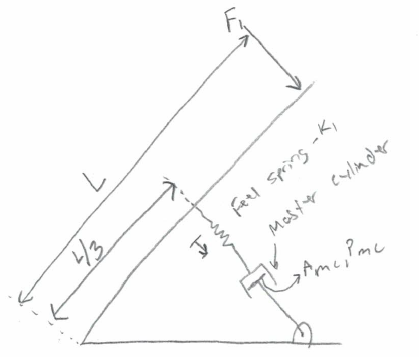

Figure 1: Brake Pedal Assembly conceptual model

From the above models, the following equation can be derived to describe the master cylinder output pressure for a given pedal force input. The master cylinder volume displacement was obtained from the CAD model of the brake pedal assembly and is also shown below. 

        
$$P_{\textrm{MC}} =\frac{3*F_1 -k_1 \left(x_{\textrm{preload}} +x\right)}{A_{\textrm{MC}} }$$


        
$$\Delta V_{\textrm{MC}} =0\ldotp 0068*\Theta$$


The BMV can be described by the model shown below:

Figure 2: BMV Conceptual Model

For the purpose of this model, spring 3 is assumed to impart a neglible force and is therefore ignored. Its purpose is to return the spool valve to its nominal position when no master cylinder pressure is applied. The brake output pressure can be described by the following equation:

        
$$P_2 =\frac{P_{\mathrm{MC}} A_1 +k_2 x_2 }{A_2 }$$


The deceleration of the aircraft after it touches down can be simply described by the following psuedo equation:

        
$$a_x =\frac{\textrm{Engine}\;\textrm{Thrust}+\textrm{Runway}\;\textrm{Downslope}\;\textrm{Force}-\textrm{rolling}\;\textrm{friction}-\textrm{Drag}-\textrm{Brake}\;\textrm{Force}}{m}$$


In a more mathematical sense this equation turns into:

        
$$a_x =\frac{T_{\textrm{engines}} -\textrm{mg}*\sin \left(\Theta_{\textrm{runway}} \right)-\mu_{\textrm{rolling}} *\textrm{mg}-\frac{1}{2}\rho {\textrm{AC}}_d v^2 -P_{\textrm{brakes}} A_{\textrm{brakes}} *\frac{r_{\textrm{brake}} }{r_{\textrm{tire}} }}{m}$$


Now we can describe the landing rollout of the aircraft and can control the deceleration rate of the plane by adjusting the brake pedal inputs of the pilot. So what ouputs of the model do we care about? We mostly care about predicting the aircraft deceleration rate for a given pedal input force and displacement. We also care about how much energy is absorbed by the brakes during the landing rollout, as the brakes will be deteriated if they absorb to much energy. It will be important to show the unceratinity surrounding the outputs of the model given the uncertaintity in all the input variables of the mdoel. For the purpose of this project, I will assume that I have already chosen the BMV spring and will focus on how certain the model is in predciting the brake pedal force and displacement, as well as how certain the model is in the prediction of the energy consumption of the brakes during a landing rollout. 

These 2 conceptual models were turned into a simulink model which is depicted below:

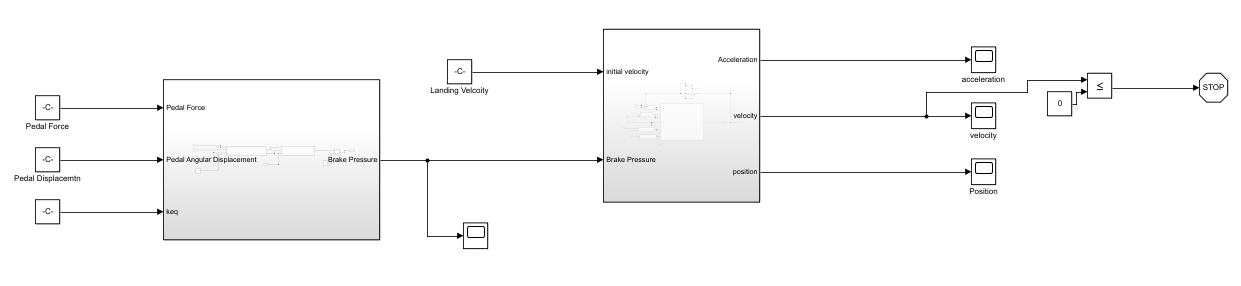

Figure 3: Simulink Model

#### Acquire and Analyze Input Data

The variables determined to have the most signficant impact on uncertaintity are:

- Engine Thrust

- Brake Coefficient of Friction

- BMV Spring Constant

- Brake Pedal Feel spring

- Mass of the airplane

- Air Density

During my internship, I designed and performed experiments to obtain data to validate the BMV model. I also aquired data on the brake pedal feel springs and BMV springs from the manufacturer of the springs. The brake coefficient of friction was determined through researching brake pads used on cars since no other data was availble. Historical weather data at the proposed aircraft testing site will be used to determine any input uncertaintity in the density of the air during the summer and fall months. The mass of the aircraft will be assumed to be within 5% with 90% confidence, as will the landing speed of the aircraft.  

Below, the input data is shown and analyzed.  All input data is assumed to have a normal distribution, which will later be used to perform monte carlo analysis. 

Landing_Velocity_Mean = 286.9; %ft/s
Landing_Velocity_sdev = Landing_Velocity_Mean * 0.05/1.645;

Brake_Friction_Coefficient_Data = [0.35 0.45 0.5 0.52 0.55 0.65 0.7 0.72 0.75 0.8] ;
Mean_Brake_Friction_Coefficient = mean(Brake_Friction_Coefficient_Data);
Brake_Friction_Coefficient_sdev = std(Brake_Friction_Coefficient_Data);

Historical_Air_Density = [0.002099519	0.002095169	0.002077174	0.00205492	0.002047357	0.002054161	0.002095169	0.002095038	0.002088272	0.002073973	0.002035563	0.002047779	0.002048865	0.00205568	0.002049997	0.002050339	0.002035002	0.002028341	0.002032767	0.002044666	0.002079186	0.002086426	0.002071331	0.002049997	0.00205644	0.002074463	0.002089158	0.002087596	0.002082923	0.002069795	0.002071331	0.002064837	0.002066755	0.00206522	0.002069795	0.00206673	0.002060248	0.002067139	0.002072484	0.002071672	0.002056453	0.002044347	0.002037607	0.002014229	0.002048155	0.00204698	0.002050753	0.002067113	0.002059485	0.002061775	0.002048155	0.002043656	0.002043344	0.002038805	0.002047028	0.002040295	0.002040739	0.002024756	0.002036574	0.002010548	0.002023119	0.002039322	0.002063293	0.002057211	0.002042535	0.002036945	0.002014598	0.002046653	0.002065201	0.002074024	0.002079432	0.002082534	0.002070563	0.002061389	0.002055696	0.002038805	0.002022419	0.002039848	0.002010558	0.002042652	0.002041894	0.002033492	0.002044666	0.002054541	0.002060248	0.002048155	0.002029429	0.002032024	0.002017553	0.002059488	0.002024236	0.002053428]; %slug/ft^3
Mean_Air_Density = mean(Historical_Air_Density);
Air_density_sdev = std(Historical_Air_Density); 

Runway_Downslope_Mean = 1;
Runway_Downslope_sdev = Runway_Downslope_Mean * 0.05/1.645;

Airplane_Mass_Mean = 544; %slugs
Airplane_Mass_sdev = Airplane_Mass_Mean * 0.05/1.645;

Engine_Thrust_Mean = 500; % lbs 
Engingine_Thrust_sdev = Engine_Thrust_Mean * 0.05/1.645;

Rolling_Friction_Coefficient_Mean = 0.01;
Rolling_Friction_Coefficient_sdev = Rolling_Friction_Coefficient_Mean * 0.05/1.645;

AC_d_Mean = 9.25; % ft^2S
AC_d_sdev = AC_d_Mean * 0.05/1.645;


#### Verification Procedures

First, lets run the simulation at different step sizes to ensure that the model is converged and does not depend on the step size of the solver.

Set up the workspace for a run for the simulation by assigning values to all input variables. 

BMV_Spring_Constant = 65;
Landing_Velocity = Landing_Velocity_Mean;
Air_Density = Mean_Air_Density;
AC_d = AC_d_Mean;
Runway_Downslope = Runway_Downslope_Mean;
Airplane_Mass = Airplane_Mass_Mean;
Engine_Thrust = Engine_Thrust_Mean;
Rolling_Friction_Coefficient = Rolling_Friction_Coefficient_Mean;
Brake_Friction_Coefficient = Mean_Brake_Friction_Coefficient;
BMV_Model_Relative_Error = 0;


Now the model is ready to run, lets vary the step size and ensure that the output is converged and does not depend on the step size of the model. For the purpose of determining convergence, I will use the total stoppping distance of the aircraft and the energy absorbed by the brakes as the convergence variables. 

prevEnergy = 0;
prevDistance = 0;
for deltaT = [1 0.5 0.1 0.01]
    fprintf("Step size = %f\n", deltaT)
    simOut = sim("LandinModel.slx", 'FixedStep', num2str(deltaT));
    position = simOut.Position.signals.values ;
    wheelBrakeForce = simOut.WheelBrakeForce.signals.values + zeros(length(position), 1);
    wheelBrakeForceEnergy = sum(trapz(position, wheelBrakeForce));
    fprintf("\tStopping Distance = %0.2f -> Percent Change = %.2f\n", position(end), 100* (position(end) - prevDistance)/prevDistance)
    fprintf("\tEnergy Abosrbed by Brake = %0.1f -> Percent Change = %.2f\n", wheelBrakeForceEnergy, 100*(wheelBrakeForceEnergy - prevEnergy)/prevEnergy)
    prevEnergy = wheelBrakeForceEnergy;
    prevDistance = position(end);

end

Step size = 1.000000


	Stopping Distance = 3798.83 -> Percent Change = Inf


	Energy Abosrbed by Brake = 24134300.4 -> Percent Change = Inf


Step size = 0.500000


	Stopping Distance = 3733.06 -> Percent Change = -1.73


	Energy Abosrbed by Brake = 23716471.4 -> Percent Change = -1.73


Step size = 0.100000


	Stopping Distance = 3680.33 -> Percent Change = -1.41


	Energy Abosrbed by Brake = 23381470.7 -> Percent Change = -1.41


Step size = 0.010000


	Stopping Distance = 3668.50 -> Percent Change = -0.32


	Energy Abosrbed by Brake = 23306315.1 -> Percent Change = -0.32


From the above convergence test, it can be seen that using a step size of 0.01 seconds, results in a percent change of 

position = simOut.Position.signals.values ;
velocity = simOut.Velocity.signals.values;
acceleration = simOut.Acceleration.signals.values;
drag = simOut.Drag.signals.values;
engineThrust = simOut.EngineThrust.signals.values + zeros(length(position), 1);
rollingFriction = simOut.RollingFriction.signals.values + zeros(length(position), 1);
runwayDownslope = simOut.RunwayDownslope.signals.values + zeros(length(position), 1);
wheelBrakeForce = simOut.WheelBrakeForce.signals.values + zeros(length(position), 1);

Now lets keep a record of all of the energy in the system and make sure that the conservation of energy is maintained. This will be done by calculating the energy of the aircraft at touchdown and then insuring that the addition of the energy to the aircraft from the engines and the runway downlsope and the subtraction of energy from the plane through drag, rolling friction and the wheel brakes all adds up to 0. 

Compute the net energy of the system and ensure that it is close to zero. I will define close to zero as less than 1% of the aircraft intital energy

aircraftIntitalEnergy = 1/2*Airplane_Mass*Landing_Velocity^2;

dragEnergy = -1 * sum(trapz(position, drag));
thrustEnergy = sum(trapz(position, engineThrust));
rollingFrictionEnergy = -1 * sum(trapz(position, rollingFriction));
runwayDownslopeEnergy = sum(trapz(position, runwayDownslope));
wheelBrakeForceEnergy = -1 * sum(trapz(position, wheelBrakeForce));
netEnergy = aircraftIntitalEnergy + dragEnergy + thrustEnergy + rollingFrictionEnergy + runwayDownslopeEnergy + wheelBrakeForceEnergy;
abs(netEnergy/aircraftIntitalEnergy) < 0.01

ans = logical
   1


The above output means that the conservation of energy verification test passed and the energy dissipated was within 1% of the original aircraft energy. 

#### Validation

During my time as an intern, I performed a test on the brake metering valve with 3 different springs installed to verfiy the BMV model. At the time I didn't really apply any validation techniques, I just qualatativley looked at the results and called them good. The results of this testing is shown in this section. 

42 lb/in spring

BMV_Spring_Constant = 42;
BMV_output_Pressure = [65.21	159.80	236.68	205.56	314.71	372.91	468.60	625.90	543.70	624.56	740.33	843.08	928.96	1101.09	1104.19; -98.26	108.35	128.38	160.60	313.42	414.51	397.12	558.75	602.47	686.95	731.87	851.48	938.09	991.76	1160.66; -77.26	73.47	251.77	215.90	259.88	358.31	470.72	541.49	621.64	630.73	830.40	842.96	918.52	1004.73	1097.21]';
MC_displacement  = [0.0000	0.0107	0.0214	0.0321	0.0429	0.0536	0.0643	0.0750	0.0857	0.0964	0.1071	0.1179	0.1286	0.1393	0.1500 ]';
MC_Pressure = [-11.36	3.95	19.27	34.59	49.91	65.22	80.54	95.86	111.18	126.50	141.81	157.13	172.45	187.77	203.08]';

BMV_pressure_predicted = zeros(15,1);
for i = 1:length(MC_displacement)
    Displacement = MC_displacement(i);
    Pressure = MC_Pressure(i);
    simOut = sim("BMVModel.slx", 'FixedStep', '0.01');
    BMV_pressure_predicted(i) = simOut.BMV_Out_Pressure.signals.values;
    
end
figure
plot(MC_displacement, BMV_output_Pressure, 'x');
xlabel("Master Cylinder Volumetric Displacement (in^3)")
ylabel("BMV Output Pressure (PSI)")
hold on;
plot(MC_displacement, BMV_pressure_predicted);
hold off;

Figure 4: BMV Output Pressure vs MC Volumetric Displacement(42 lb/in spring)

In the figure above, the BMV model is plotted with the experiment results for the BMV with the 42 lb/in spring installed. As can be seen, the model fairly closely precits the output of the BMV. Below this error is quantified and will later be used in a monte carlo simulation.

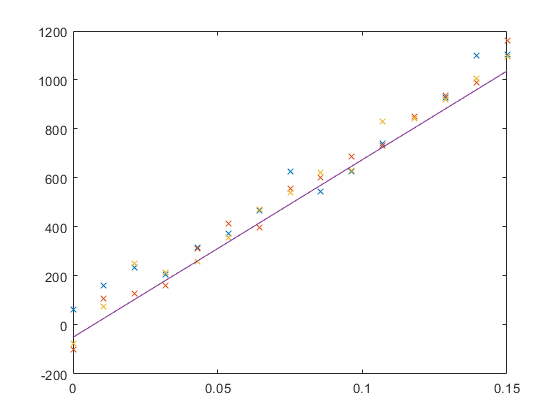

relative_pressure_error_42 = BMV_output_Pressure - BMV_pressure_predicted;
figure
subplot(1,2,1)

histogram(relative_pressure_error_42, 6)
xlabel("Relative Pressure Error (PSI)")
ylabel("Frequency")
[relative_pressure_error_cdf_42, relative_pressure_error_42] = ecdf(reshape(relative_pressure_error_42,[],1));
subplot(1,2,2)
plot(relative_pressure_error_cdf_42, relative_pressure_error_42);

Figure 5: Relative Pressure Error Histogram and CDF for 42 lb/in spring

The CDF shown above will be used during the monte carlo simulation to provide random error in the BMV model. Similar CDFs will be created for the other 2  spring constants but will not be shown. 

xlabel("CDF")
ylabel("Relative Pressure Error (PSI)")

51 lb/in spring

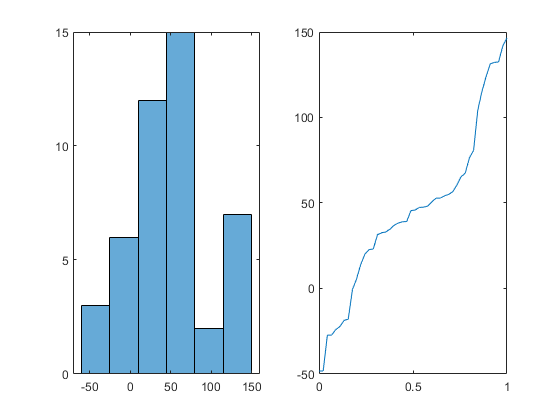

BMV_Spring_Constant = 51;

BMV_output_Pressure = [20.92	106.00	167.27	252.28	321.52	453.44	457.51	545.17	694.23	735.65	840.81	937.34	1050.03	1068.79	1196.01; 43.43	86.72	115.72	217.88	277.83	418.41	529.59	630.11	748.81	805.49	844.72	945.20	1016.85	1090.37	1152.49; -2.88	57.43	161.57	224.84	348.82	438.44	505.27	571.49	721.83	763.86	816.77	934.71	1049.07	1064.08	1195.47]';
MC_displacement  = [0.0000	0.0107	0.0214	0.0321	0.0429	0.0536	0.0643	0.0750	0.0857	0.0964	0.1071	0.1179	0.1286	0.1393	0.1500 ]';
MC_Pressure = [0.00	16.83	33.66	50.50	67.33	84.16	100.99	117.83	134.66	151.49	168.32	185.16	201.99	218.82	235.65]';

BMV_pressure_predicted = zeros(15,1);
for i = 1:length(MC_displacement)
    Displacement = MC_displacement(i);
    Pressure = MC_Pressure(i);
    simOut = sim("BMVModel.slx", 'FixedStep', '0.01');
    BMV_pressure_predicted(i) = simOut.BMV_Out_Pressure.signals.values;
    
end
figure
plot(MC_displacement, BMV_output_Pressure, 'x');
hold on;
plot(MC_displacement, BMV_pressure_predicted);
hold off;

Figure 6: BMV Output Pressure vs MC Volumetric Displacement(51 lb/in spring)

In the figure above, the BMV model is plotted with the experiment results for the BMV with the 42 lb/in spring installed. As can be seen, the model fairly closely precits the output of the BMV. Below this error is quantified and will later be used in a monte carlo simulation.

relative_pressure_error_51 = BMV_output_Pressure - BMV_pressure_predicted;
[relative_pressure_error_cdf_51, relative_pressure_error_51] = ecdf(reshape(relative_pressure_error_51,[],1));


65 lb/in spring

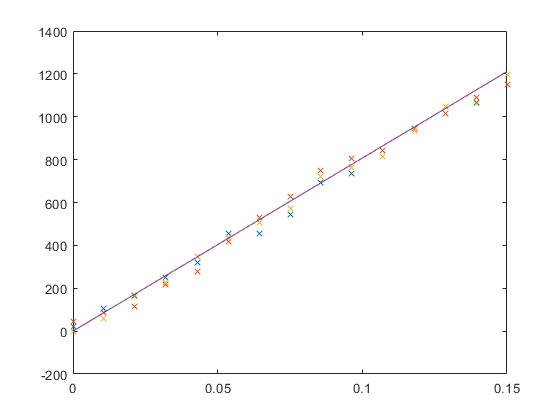

BMV_Spring_Constant = 65;
BMV_output_Pressure = [-7.26	89.96	206.60	392.83	505.72	592.20	682.44	755.12	897.65	962.10	1105.95	1230.59	1313.84	1400.48	1551.08 ; 30.79	79.13	276.88	316.62	478.86	514.16	662.17	785.21	868.29	935.06	1052.94	1229.47	1370.93	1454.96	1480.01; -55.02	67.05	214.97	356.12	435.01	539.47	699.97	814.92	808.69	893.28	1092.46	1206.64	1315.77	1317.29	1523.44]';

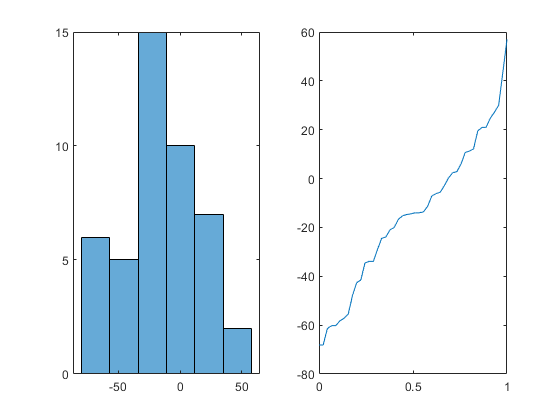

MC_displacement  = [0.0000	0.0107	0.0214	0.0321	0.0429	0.0536	0.0643	0.0750	0.0857	0.0964	0.1071	0.1179	0.1286	0.1393	0.1500 ]';
MC_Pressure = [0.00	22.39	44.77	67.16	89.55	111.93	134.32	156.71	179.09	201.48	223.87	246.25	268.64	291.03	313.41]';

BMV_pressure_predicted = zeros(15,1);
for i = 1:length(MC_displacement)

    Displacement = MC_displacement(i);
    Pressure = MC_Pressure(i);
    simOut = sim("BMVModel.slx", 'FixedStep', '0.01');
    BMV_pressure_predicted(i) = simOut.BMV_Out_Pressure.signals.values; 
end
figure
plot(MC_displacement, BMV_output_Pressure, 'x');
hold on;
plot(MC_displacement, BMV_pressure_predicted);
hold off;

Figure 7: BMV Output Pressure vs MC Volumetric Displacement(65 lb/in spring)

In the figure above, the BMV model is plotted with the experiment results for the BMV with the 42 lb/in spring installed. As can be seen, the model fairly closely precits the output of the BMV. Below this error is quantified and will later be used in a monte carlo simulation.

relative_pressure_error_65 = BMV_output_Pressure - BMV_pressure_predicted;
[relative_pressure_error_cdf_65, relative_pressure_error_65] = ecdf(reshape(relative_pressure_error_65,[],1));


#### Predictive Simulation

Now that we have input uncertainity as well as relative model error for the Brake Metering Valve, let us perform a simulation to predict the deceleration rate of the aircraft for a given input pedal force and angular displacement. The input force and displacement is a pilot preference and will be taken as absolute with no error associated with it. We will run the simulation 3 times, one time for each BMV replacement spring. 

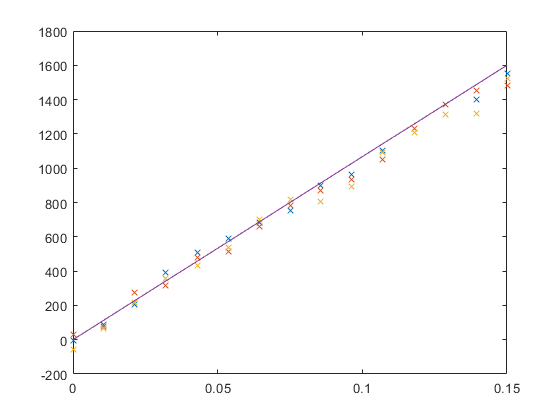

Pedal_Force = 50;
Pedal_Angular_Displacement = 9;

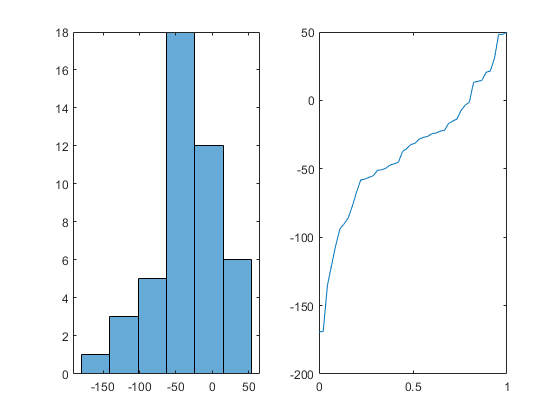

BMV_Spring_Constant = 42;

num_iterations = 200;
num_samples = 5;

iteration_number = zeros(num_iterations,1);
Deceleration = zeros(num_iterations, num_samples);
Mean_Deceleration = zeros(num_iterations, num_samples);
Std_Deceleration = zeros(num_iterations, num_samples);
Brake_Energy = zeros(num_iterations, num_samples);
Mean_Brake_Energy = zeros(num_iterations, num_samples);
Std_Brake_Energy = zeros(num_iterations, num_samples);
for sample_number = 1:num_samples
    for n=1:num_iterations
        iteration_number(n) = n;
        Landing_Velocity = norminv(rand(1,1),Landing_Velocity_Mean, Landing_Velocity_sdev);
        Air_Density = norminv(rand(1,1), Mean_Air_Density, Air_density_sdev);
        AC_d = norminv(rand(1,1),AC_d_Mean, AC_d_sdev);
        Runway_Downslope = norminv(rand(1,1),Runway_Downslope_Mean, Runway_Downslope_sdev);
        Airplane_Mass = norminv(rand(1,1), Airplane_Mass_Mean, Airplane_Mass_sdev);
        Engine_Thrust = norminv(rand(1,1), Engine_Thrust_Mean, Engingine_Thrust_sdev);
        Rolling_Friction_Coefficient = norminv(rand(1,1), Rolling_Friction_Coefficient_Mean, Rolling_Friction_Coefficient_sdev);
        Brake_Friction_Coefficient = norminv(rand(1,1), Mean_Brake_Friction_Coefficient, Brake_Friction_Coefficient_sdev);
        
        BMV_Model_Relative_Error = interp1(relative_pressure_error_cdf_42, relative_pressure_error_42, rand(1,1));
        
        simOut = sim("LandinModel.slx", 'FixedStep', '0.01');
        Deceleration(n, sample_number) = mean(simOut.Acceleration.signals.values);
        Mean_Deceleration(n,sample_number) = mean(Deceleration(1:n, sample_number));
        Std_Deceleration(n,sample_number) = std(Deceleration(1:n, sample_number));
        
        position = simOut.Position.signals.values ;
        wheelBrakeForce = simOut.WheelBrakeForce.signals.values + zeros(length(position), 1);
        wheelBrakeForceEnergy = sum(trapz(position, wheelBrakeForce));
        Brake_Energy(n,sample_number) = wheelBrakeForceEnergy;
        Mean_Brake_Energy(n,sample_number) = mean(Brake_Energy(1:n,sample_number));
        Std_Brake_Energy(n,sample_number) = std(Brake_Energy(1:n, sample_number));
        
    end
end


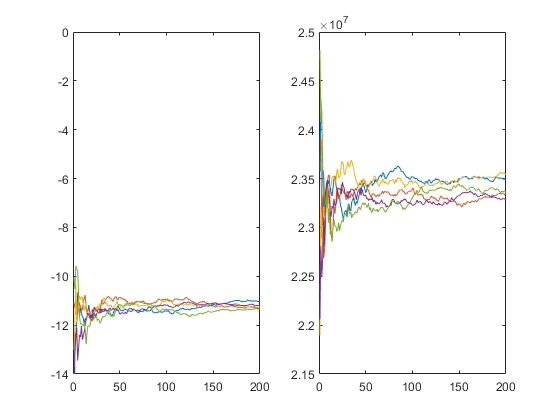

figure
subplot(1,2,1)
plot(iteration_number, Mean_Deceleration(:,:));
xlabel("Iteration #");
ylabel("Decleration (ft/s^2")
ylim([-14 0]);
subplot(1,2,2)
plot(iteration_number, Mean_Brake_Energy./1e6);

Figure 8: Monte Cralo Convergence plots for deceleration and brake energy

xlabel("Iteration #");
ylabel("Brake Energy (Millions of Ft-lbs")
mean_decel_42 = mean(Deceleration, 'all');
mean_brake_energy_42 = mean(Brake_Energy, 'all');
std_decel_42 = std(Deceleration, 0 , 'all');
std_brake_energy_42 = std(Brake_Energy, 0, 'all');

[Deceleration,Mean_Deceleration,Std_Deceleration, Brake_Energy, Mean_Brake_Energy, Std_Brake_Energy ] = run_monte_carlo(51, relative_pressure_error_cdf_51, relative_pressure_error_51);

mean_decel_51 = mean(Deceleration, 'all');
mean_brake_energy_51 = mean(Brake_Energy, 'all');
std_decel_51 = std(Deceleration, 0 , 'all');
std_brake_energy_51 = std(Brake_Energy, 0, 'all');

[Deceleration,Mean_Deceleration,Std_Deceleration, Brake_Energy, Mean_Brake_Energy, Std_Brake_Energy ] = run_monte_carlo(65, relative_pressure_error_cdf_65, relative_pressure_error_65);

mean_decel_65 = mean(Deceleration, 'all');
mean_brake_energy_65 = mean(Brake_Energy, 'all');
std_decel_65 = std(Deceleration, 0 , 'all');
std_brake_energy_65 = std(Brake_Energy, 0, 'all');



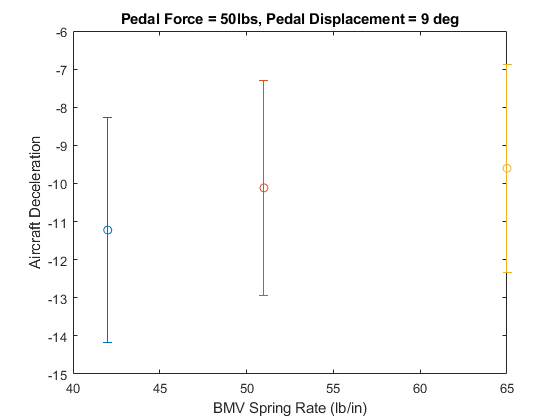

figure
errorbar(42, mean_decel_42, std_decel_42, 'o')
hold on
errorbar(51, mean_decel_51, std_decel_51, 'o')
errorbar(65, mean_decel_65, std_decel_65, 'o')
title("Pedal Force = 50lbs, Pedal Displacement = 9 deg")
xlabel("BMV Spring Rate (lb/in)");
ylabel("Aircraft Deceleration")

hold off

Figure 9: Predicted Aircraft Decleration vs BMV Spring Rate

In the above figure it can be seen that as the BMV spring rate increases, the aircraft decerlation rate also increases. However due to the large 90% confident bounds it is difficult to determine which spring should be chosen at this time. This is exactly the conclusion that I came to during my internship and it is why we chose to order three seperate springs. This model gives a good indication of the range of values that could be expected from the springs chosen, but being able to swap out springs during aircraft ground testing would allow for fine tuning of the brake pedals to the pilots liking. This plot would have been very helpful to explain to my team members how much uncertaintity there was in the model, mostly due to input parameters to the model. 

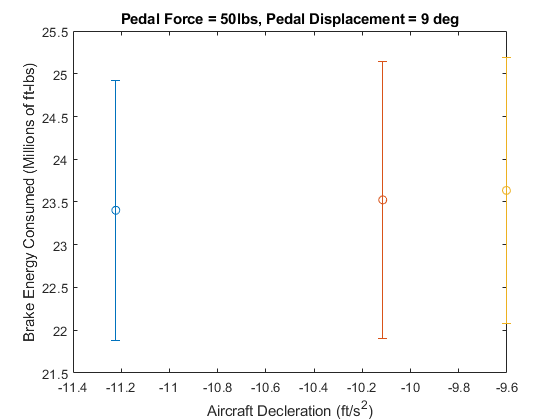

figure 
errorbar(mean_decel_42, mean_brake_energy_42./1e6, std_brake_energy_42./1e6, 'o')
hold on
errorbar(mean_decel_51,mean_brake_energy_51./1e6, std_brake_energy_51/1e6, 'o')
errorbar(mean_decel_65, mean_brake_energy_65./1e6, std_brake_energy_65./1e6, 'o')
title("Pedal Force = 50lbs, Pedal Displacement = 9 deg")
xlabel("Aircraft Decleration (ft/s^2)");
ylabel("Brake Energy Consumed (Millions of ft-lbs)")
hold off

Figure 10: Predicted Brake Energy Consumption vs Aircraft Deceleration

In the figure above the brake energy consumption is shown vs aircraft deceleration. The energy absorbed by the brakes is fairly constant and it is important to note the brakes had a maximum energy capacity of 26 million ft-lbs. This model helps drive home the fact that the brakes would not absorb more than their capacity in this worst case landing scenario with 90% confidence. This plot would have been very helpful to present during my internship as it gives more confidence in the brakes ability to absorb energy in this worst case landing scenario. 

#### Conclusions

 To keep this report from going on forever, I have decided this meets the requirements of the assigment. There are however many other things that we I learned from this class that could be applied to give more helpfule information. One such thing is looking into the contributions of each input model uncertaintity to see which inputs contribute the most to the error bands of the model. With this information, more resources could be inteligently redirected to support reducing the uncertaintity sources. 

Overall, this project was very helpful in helping me realize the true potential of the material of this class. I had struggled to "trust" my model during my internship since I was unsure how to perform this type of analysis which quantifies how "trustworthy" the model is. Now that I have these tools, I feel that I will be a better overall engineer since I will not have to blindly trust a model to be accurate. Also, I liked the open endendness of this project, since in my experience that is how the real world works. I have always said that in industry the math is not the difficult part of the problem (like it is in school), it is coming up with the assumptions that go into the model and knowing when you've done enough (but not too much) analysis. I believe it takes years of experience to become good at this and this class and this project is another good stepping stone for me in that direction. 